clear 
clc

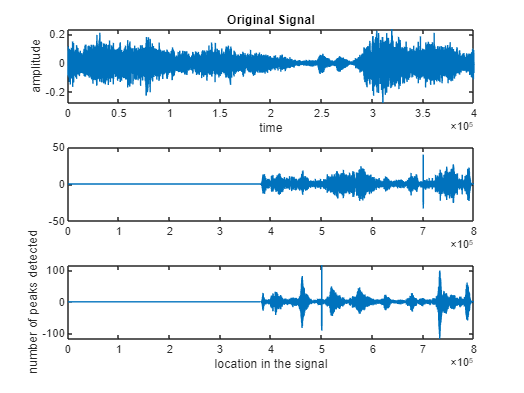

% Load audio file
[data, fs] = audioread('audio.wav');

% Load standard pulse
load('Pulse.mat'); % Assuming Pulse.mat contains the variable 'Pulse'

% Play audio
%sound(data, fs);
% zero padding yp
y_p=zeros(400000,1);
y_p(1:22051)=yp;
% Perform matched filtering on each channel
filtered_signals = zeros(799999,2);
for i = 1:size(data, 2)
    filtered_signals(:, i) = xcorr(data(:, i), y_p);
end

% Find peak locations in the filtered signal
[pks, locs] = findpeaks(abs(filtered_signals(:, 1)), 'MinPeakHeight', 0.5);


% Plot filtered signals
figure;
subplot(3, 1, 1);
plot(data(:, 1)); % Plot original signal
title('Original Signal');
xlabel('time')
ylabel('amplitude')

subplot(3, 1, 2);
plot(filtered_signals(:, 1)); % Plot filtered signal
subplot(3, 1, 3);
plot(filtered_signals(:, 2)); % Plot filtered signal
% plot(locs, pks, 'ro'); % Mark detected pulses
title('Filtered Signal channel 2');
xlabel('location in the signal')
ylabel('')